clc
clear

## Generate a DOGPUP mesh

*Meshing is facilitated by the iso2mesh toolbox, see: *[*https://iso2mesh.sourceforge.net/cgi-bin/index.cgi*](https://iso2mesh.sourceforge.net/cgi-bin/index.cgi)* and *[*https://github.com/fangq/iso2mesh*](https://github.com/fangq/iso2mesh) 

[node,~,elem] = meshabox([0 0 0],[60 30 60],1.2); % 60 x 30 x 60 mm mesh

generating tetrahedral mesh from closed surfaces ...
creating volumetric mesh from a surface mesh ...
volume mesh generation is complete



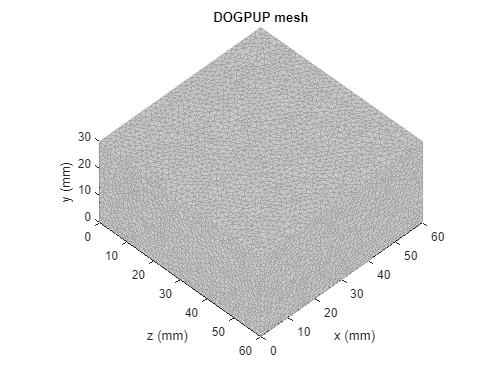

elem = elem(:,1:4);
[node,elem] = sortmesh([],node,elem); % optimise node and element ordering

% initialise DOGPUP mesh
mua = 0.008; % absorption (mm^-1)
musp = 1; % reduced scattering (mm^-1)
nr = 1.4; % refractive index
mesh = dMesh(node,elem,nr,[mua musp]);

% plot mesh
figure
plotdmesh(mesh,0.9)
title('DOGPUP mesh')

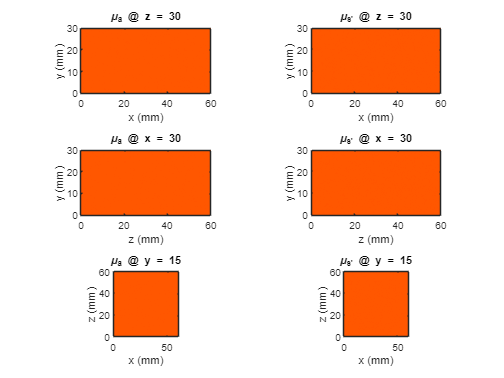


% plot mesh optical proeprties
figure
tiledlayout(3,2)
nexttile
plotfun_slice(mesh,mesh.mua,hot,'z=30')
title('\mu_a @ z = 30')
nexttile
plotfun_slice(mesh,mesh.musp,hot,'z=30')
title('\mu_s'' @ z = 30')
nexttile
plotfun_slice(mesh,mesh.mua,hot,'x=30')
title('\mu_a @ x = 30')
nexttile
plotfun_slice(mesh,mesh.musp,hot,'x=30')
title('\mu_s'' @ x = 30')
nexttile
plotfun_slice(mesh,mesh.mua,hot,'y=15')
title('\mu_a @ y = 15')
nexttile
plotfun_slice(mesh,mesh.musp,hot,'y=15')
title('\mu_s'' @ y = 15')

## **Update optical properties**

Add some noise to the absorption and reduced scattering.

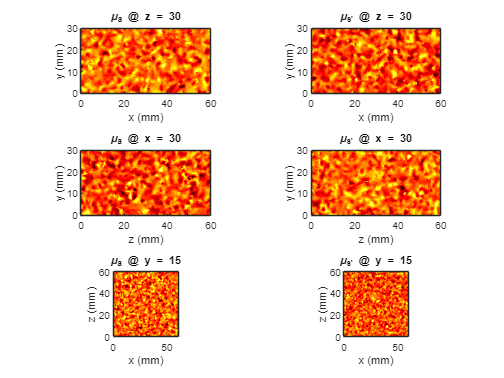

% add gaussian white noise
mua_i = mua.*0.05.*randn(size(mesh.mua)) + mua;
musp_i = musp.*0.05.*randn(size(mesh.mua)) + musp;
% update
mesh = update_properties(mesh,[mua_i musp_i]);

% plotting
figure
tiledlayout(3,2)
nexttile
plotfun_slice(mesh,mesh.mua,hot,'z=30')
title('\mu_a @ z = 30')
nexttile
plotfun_slice(mesh,mesh.musp,hot,'z=30')
title('\mu_s'' @ z = 30')
nexttile
plotfun_slice(mesh,mesh.mua,hot,'x=30')
title('\mu_a @ x = 30')
nexttile
plotfun_slice(mesh,mesh.musp,hot,'x=30')
title('\mu_s'' @ x = 30')
nexttile
plotfun_slice(mesh,mesh.mua,hot,'y=15')
title('\mu_a @ y = 15')
nexttile
plotfun_slice(mesh,mesh.musp,hot,'y=15')
title('\mu_s'' @ y = 15')

Add spherical inclusions

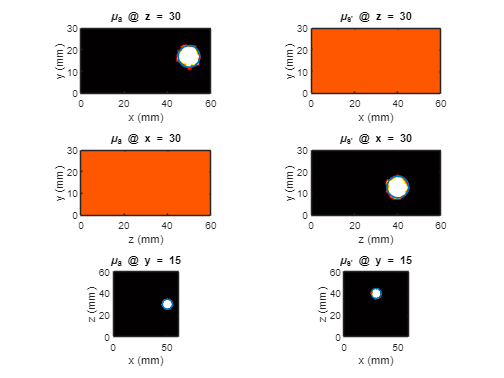

incl = [50 17 30 5; 30 13 40 5]; % inclusion position and radius

mua_i(:) = mua;
musp_i(:) = musp;

% index inclusion 1 usinf equation of sphere 
idx1 = (mesh.node(:,1) - incl(1,1)).^2 + (mesh.node(:,2) - incl(1,2)).^2 + (mesh.node(:,3) - incl(1,3)).^2 < incl(1,4)^2;
% index inclusion 2 usinf equation of sphere 
idx2 = (mesh.node(:,1) - incl(2,1)).^2 + (mesh.node(:,2) - incl(2,2)).^2 + (mesh.node(:,3) - incl(2,3)).^2 < incl(1,4)^2;

% update properties
mua_i(idx1) = 0.015;
musp_i(idx2) = 1.2;
mesh = update_properties(mesh,[mua_i musp_i]);

% plotting
figure
tiledlayout(3,2)
nexttile
plotfun_slice(mesh,mesh.mua,hot,'z=30',incl(1,:))
title('\mu_a @ z = 30')
nexttile
plotfun_slice(mesh,mesh.musp,hot,'z=30',incl(2,:))
title('\mu_s'' @ z = 30')
nexttile
plotfun_slice(mesh,mesh.mua,hot,'x=30',incl(1,:))
title('\mu_a @ x = 30')
nexttile
plotfun_slice(mesh,mesh.musp,hot,'x=30',incl(2,:))
title('\mu_s'' @ x = 30')
nexttile
plotfun_slice(mesh,mesh.mua,hot,'y=15',incl(1,:))
title('\mu_a @ y = 15')
nexttile
plotfun_slice(mesh,mesh.musp,hot,'y=15',incl(2,:))
title('\mu_s'' @ y = 15')

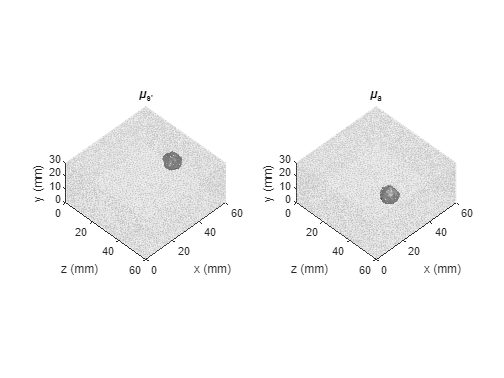


figure
tiledlayout(1,2)
nexttile
plotfun_vol(mesh,mesh.mua)
title('\mu_s''')
nexttile
plotfun_vol(mesh,mesh.musp)
title('\mu_a')

## Add sources and detectors

use DOGPUP optode object to place array of sources and detectors on mesh

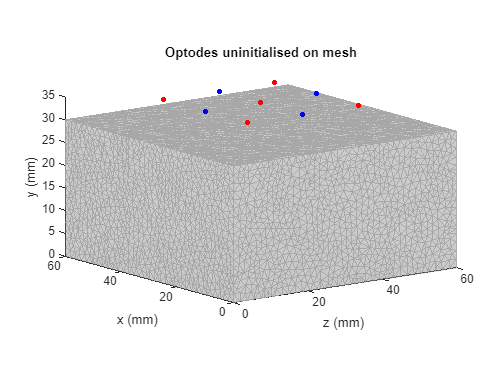

% Initialise optode class

% Source stats
dt = 50e-12;
tAxis = 0:dt:(140*dt);
% Source TPSF
avgPow = 1e3;
fwhm = 250e-12;
time_dev = fwhm./(2*sqrt(2*log(2)));
tpsf = exp(-((tAxis-6.*time_dev).^2)./(2.*(time_dev).^2));
Nf = 30; % number of Fourier series coefficients for decomposition

% Optode locations
origin = [30 35 30];
[X,Z] = meshgrid(linspace(-15,15,3),linspace(-15,15,3));
% source locations
Xs = X(1:2:end).';
Zs = Z(1:2:end).';
s_pos = origin + [Xs zeros(numel(Xs),1) Zs];
% source locations
Xs = X(2:2:end-1).';
Zs = Z(2:2:end-1).';
d_pos = origin + [Xs zeros(numel(Xs),1) Zs];
% source-detector links, set here to link all sources and detectors
link = repelem((1:size(s_pos,1)).',size(d_pos,1));
link = cat(2,link,kron(ones(size(s_pos,1),1),(1:size(d_pos,1)).'));

% initialise DOGPUP optode object
optode = dOptode(s_pos,d_pos,link,avgPow,tpsf,tAxis,Nf);

figure
hold on
plotdmesh(mesh,0.9)
scatter3(optode.s_positions(:,3),optode.s_positions(:,1),optode.s_positions(:,2),20,'r','filled')
scatter3(optode.d_positions(:,3),optode.d_positions(:,1),optode.d_positions(:,2),20,'b','filled')
view(-37,12)
title('Optodes uninitialised on mesh')

Adding optode to mesh snaps the optodes to the nearest surface

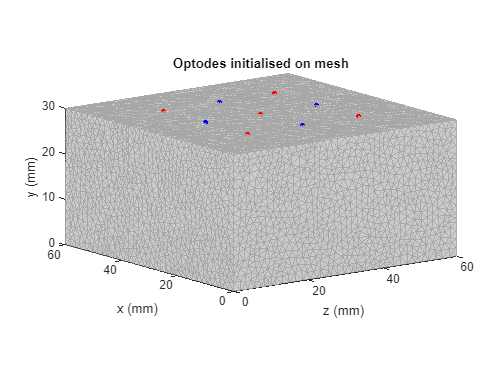

mesh = add_optode(mesh,optode);
figure
plotdmesh_snd(mesh,0.9,false)
view(-37,12)
title('Optodes initialised on mesh')

DOGPUP mesh class references optode handle, so any modification to optode properties are relfected in the mesh

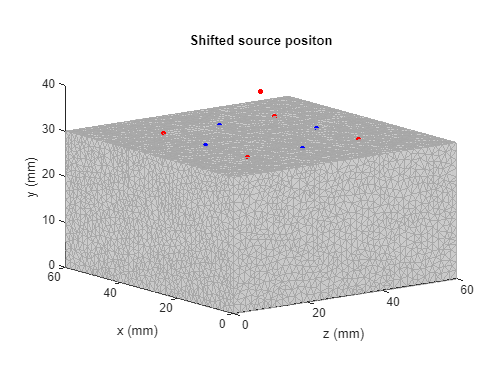

optode.s_positions(3,:) = optode.s_positions(3,:) + [0 10 0];

figure
plotdmesh_snd(mesh,0.9,false)
view(-37,12)
title('Shifted source positon')


optode.s_positions(3,:) = optode.s_positions(3,:) - [0 10 0]; % reset

If you want more than one instance of the optodes the class is copyable. Manipulating copied optode does not affect mesh

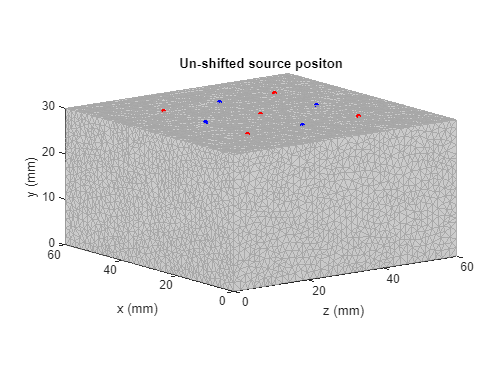

optode_c = copy(optode);
optode_c.s_positions = optode_c.s_positions+ [0 10 0];

figure
plotdmesh_snd(mesh,0.9,false)
view(-37,12)
title('Un-shifted source positon')